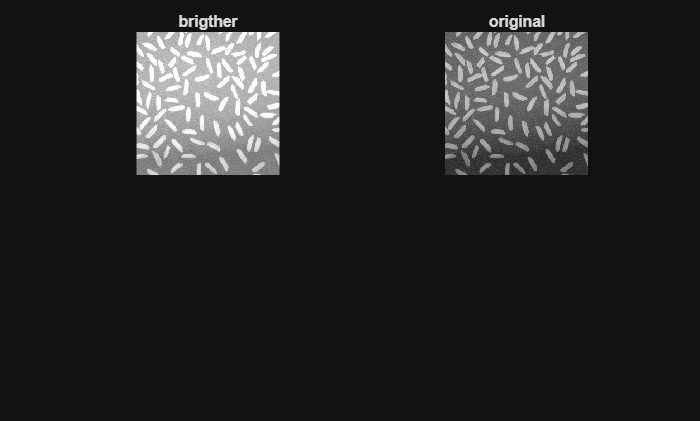

img = imread(which('rice.png'));
i_double = im2double(img);
i_bright = i_double + 0.3;
img_8 = im2uint8(i_bright);
figure;
    subplot(2,2,1)
        imshow(img_8);
        title("brigther");
    subplot(2,2,2);
        imshow(img);
        title("original");

ดูค่าทางสถิติ

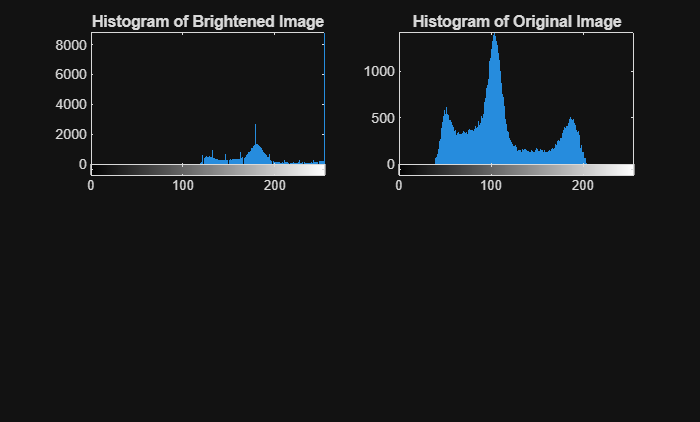

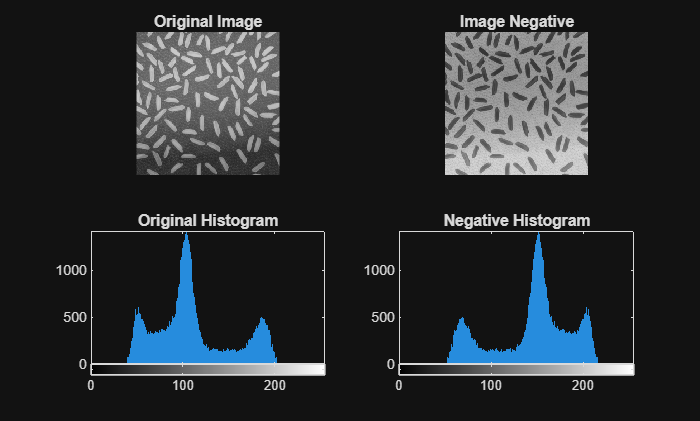

close all;
figure;
    subplot(2,2,1);
    imhist(img_8);
    title("Histogram of Brightened Image");
    axis tight;
    subplot(2,2,2);
    imhist(img);
    axis tight;
    title("Histogram of Original Image");

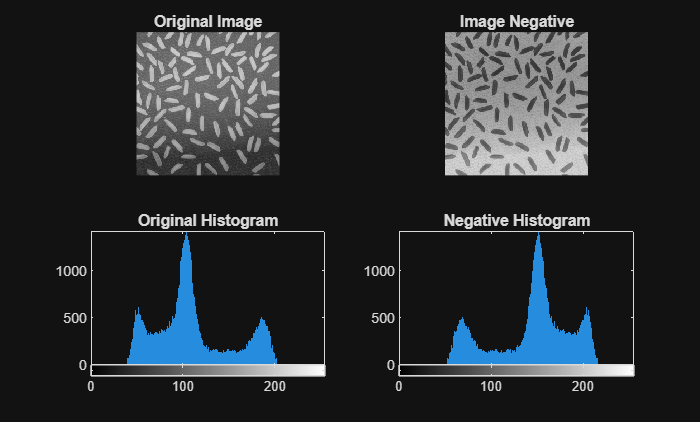

% 1. We already have img_double from the previous step
%    (If running this section alone, uncomment the next two lines)
% img = imread(which('rice.png'));
% img_double = im2double(img);

% 2. Subtract every pixel value from 1.0
img_negative_double = 1.0 - img_double;

% 3. Convert back to uint8
img_negative_uint8 = im2uint8(img_negative_double);

% --- Display Results ---
figure;
    subplot(2, 2, 1);
        imshow(img);
        title('Original Image');

    subplot(2, 2, 2);
        imshow(img_negative_uint8);
        title('Image Negative');

    subplot(2, 2, 3);
        imhist(img);
        title('Original Histogram');
        axis tight;

    subplot(2, 2, 4);
        imhist(img_negative_uint8);
        title('Negative Histogram');
        axis tight;

### **2.1 Manual Thresholding**

Based on the histogram, the valley is around 100-120. Let's try a manual threshold value of `100`.

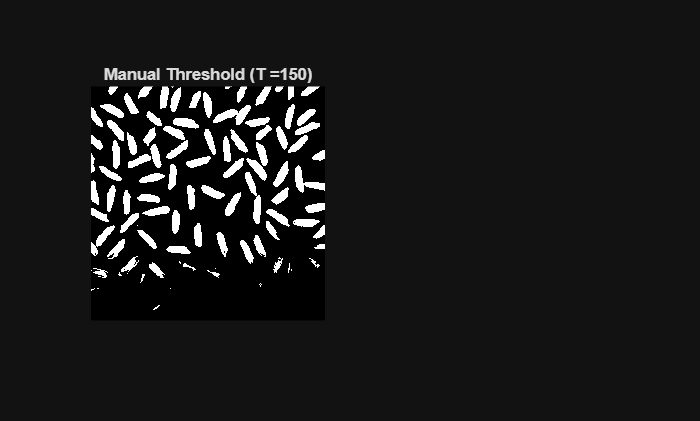

% Set a manual threshold
T_manual = 150;

% Any pixel > 100 becomes 1 (white)
% Any pixel <= 100 becomes 0 (black)

BW_manual = img > T_manual;

figure;
    subplot(1, 2, 1);
    imshow(BW_manual);
    title(['Manual Threshold (T =', num2str(T_manual), ')']);

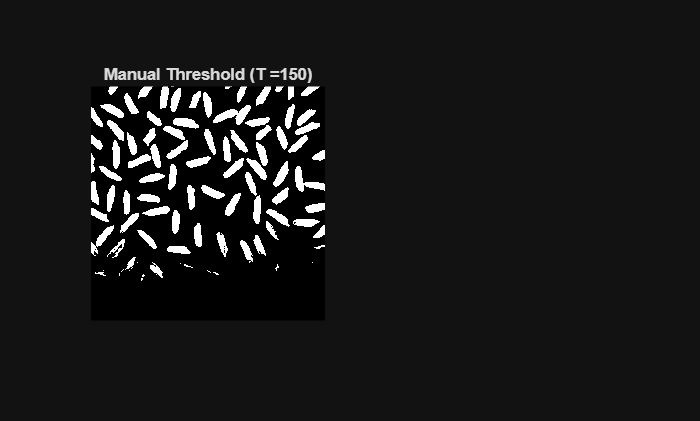

% negative
T = 100;
BW = img_negative_uint8 < T;
figure;
    subplot(1, 2, 1);
    imshow(BW);
    title(['Manual Threshold (T =', num2str(T_manual), ')']);

% automatic-threshold
t_a = graythresh(img);
disp(t_a);

    0.5137



t_uint8 = t_a*255;
disp(t_uint8);

   131



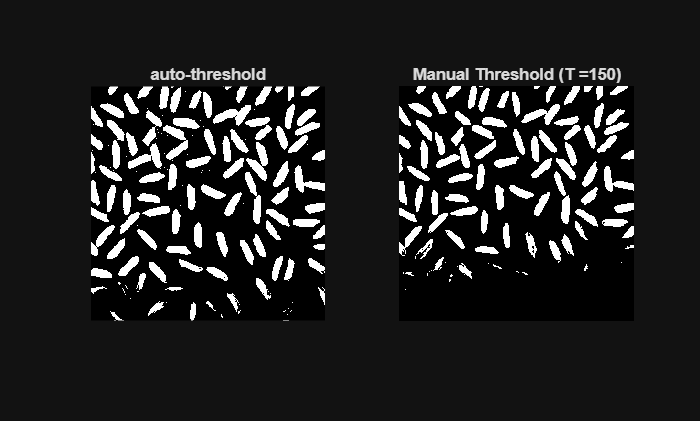

a_img = img > t_uint8;
close all;
figure;
    subplot(1,2,1);
    imshow(a_img);
    title("auto-threshold");
        subplot(1, 2, 2);
            imshow(BW);
            title(['Manual Threshold (T =', num2str(T_manual), ')']);